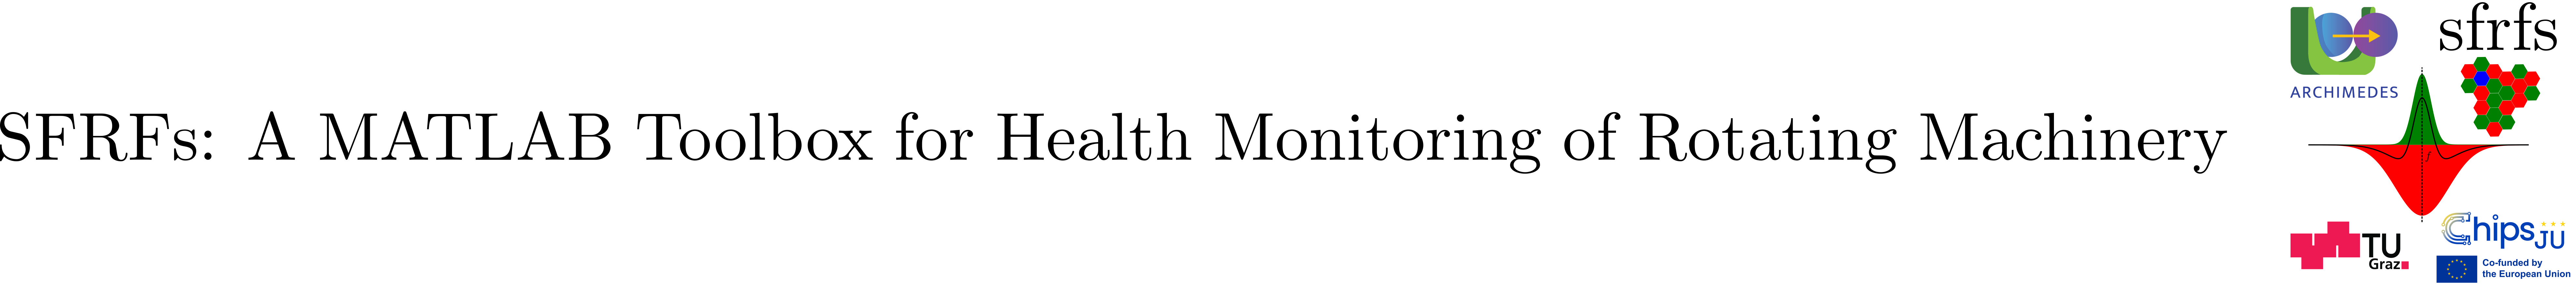

# PolarityReversalDetector

## Summary

`PolarityReversalDetector` is a static utility class that detects polarity reversals in harmonic-indexed contrast responses. It identifies changes between successive nonzero contrast polarities, ignoring zero-valued observations without resetting the previously observed polarity state.

**Key features:**

- Detects polarity reversals independently for each harmonic.

- Ignores zero-valued contrast observations without resetting the stored polarity.

- Supports sequential snapshot processing with explicitly maintained polarity state.

- Computes reversal-event masks over complete contrast trajectories.

- Reports reversal locations, counts, and rates for individual harmonics.

- Validates contrast inputs and detector states.

The class provides a computational mechanism for identifying polarity reversal events in harmonic-resolved spectral contrast representations, supporting the contrast polarity analysis framework presented in [3].

## Description

`PolarityReversalDetector` provides static methods for detecting changes in the polarity of harmonic-indexed contrast responses, both sequentially and over complete observation trajectories.

For each harmonic, polarity is determined by the sign of its contrast response. A reversal occurs when a nonzero contrast has the opposite sign to the previously observed nonzero contrast. Zero-valued observations are ignored: they neither generate reversal events nor modify the stored polarity state.

The `detect` method processes a single contrast snapshot using an explicitly supplied polarity-state vector. It returns the indices of harmonics exhibiting reversals and the updated state. Initial states equal to zero indicate that no nonzero polarity has yet been observed.

The `detectAll` method processes a contrast trajectory with observations arranged in rows and harmonics in columns. It maintains independent polarity states for each harmonic and returns a logical matrix identifying reversal events at their corresponding observation and harmonic positions.

The `summarize` method extends trajectory-wide detection by reporting reversal-event locations, counts, and rates for each harmonic. Reversal rates are normalized by the number of observation transitions, using the denominator `max(T−1, 1)` for a trajectory of `T` observations.

The class operates on signed contrast representations and does not compute receptive-field responses, center–surround contrast, or cross-sensor agreement. It can therefore be used downstream of `ContrastPolarityFilter` or independently with other signed contrast trajectories.

**See also:** [`ContrastPolarityFilter`](matlab:open('./ContrastPolarityFilter.mlx')), [`ContrastMappings`](matlab:open('./ContrastMappings.mlx')), [`LiftedHarmonicResponseCompute`](matlab:open('./LiftedHarmonicResponseCompute.mlx')).

## Public methods

### detect

Detects harmonic polarity reversal events in a single contrast snapshot using an explicitly supplied polarity state.

For each harmonic, the method compares the sign of the current contrast with the previously stored nonzero polarity. A reversal is detected when the two polarities are opposite. Zero-valued contrasts do not generate events or modify the stored state.

The method returns the indices of harmonics exhibiting reversals and the updated polarity state. The class does not retain state internally.

#### Syntax

`[Hrev, state] = PolarityReversalDetector.detect(c, state);`

#### Parameters

#### Output

Let $c_h$ denote the current contrast and $\sigma_h$ the previously stored polarity of harmonic ($h$). A reversal is detected when


$$\upsilon_h = \mathrm{sgn}(c_h)$$



$$\upsilon_h \neq 0,\qquad \sigma_h\upsilon_h < 0$$


The updated state is


$$\sigma'_h = \mathrm{sgn}(c_h) + \sigma_h(1-|\mathrm{sgn}(c_h)|)$$


Thus, zero-valued observations are ignored, and reversals are identified between successive nonzero polarities.

The updated `state` must be supplied explicitly to subsequent calls when processing a sequence of observations.

### detectAll

Detects harmonic polarity reversal events over a complete contrast trajectory.

The method processes successive contrast snapshots in chronological order, maintaining an independent polarity state for each harmonic. A reversal is detected whenever a nonzero contrast has the opposite sign to the last observed nonzero polarity. Zero-valued observations do not generate events or reset the stored polarity.

Unlike `detect`, this method initializes and updates the polarity state internally during trajectory processing. No initial state needs to be supplied.

#### Syntax

`eventMask = PolarityReversalDetector.detectAll(C);`

#### Parameters

#### Output

For a contrast trajectory $C\in\mathbb{R}^{T\times H}$, the method initializes the polarity state to zero for all $H$ harmonics and sequentially applies the reversal-detection procedure described in `detect`.

The resulting event mask has dimensions $T\times H$. Each harmonic is processed independently, and the first nonzero observation of a harmonic establishes its initial polarity without generating a reversal event.

The method returns an unsigned logical event mask. It does not return the signed reversal-event representation defined in Algorithm 2 of [3].

### **summarize**

Summarizes harmonic polarity reversal events over a complete contrast trajectory.

The method detects polarity reversals independently for each harmonic and constructs a summary containing the event mask, event locations, reversal counts, and reversal rates.

Reversal detection follows the same zero-ignoring semantics as `detect` and `detectAll`. Rates are normalized by the number of observation transitions rather than by the number of nonzero contrast observations.

#### Syntax

`summary = PolarityReversalDetector.summarize(C);`

#### Parameters

#### Output

Returns a structure `summary` containing:

For a contrast trajectory with $T$ observations and $H$ harmonics, let $E\in{0,1}^{T\times H}$ denote the logical reversal-event mask.

The reversal count for harmonic $h$ is


$$N_h=\sum_{t=1}^{T}E_{t,h}.
$$


The corresponding reversal rate is


$$R_h=\frac{N_h}{\max(T-1,1)}.
$$


The method obtains event locations using MATLAB's column-major indexing convention. Consequently, `SnapshotIndex` and `HarmonicIndex` identify corresponding event positions, ordered first by harmonic column and then by observation index.

Reversal rates quantify events per observation transition; they are not normalized by elapsed physical time or by the number of nonzero observations.

## Example

This example illustrates harmonic polarity reversal detection using a deterministic synthetic contrast trajectory. Six harmonic channels exhibit different polarity behaviors, including persistent polarity, genuine reversals, intermittent zero-valued observations, and delayed activation.

The experiment demonstrates all three public methods: `detect`, `detectAll`, and `summarize`. It also verifies that sequential detection and trajectory-wide detection produce identical event masks.

### **Synthetic ****harmonic ****contrast ****trajectory**

We construct 24 observations with six harmonic channels. Each channel follows a deliberately defined polarity sequence so that its reversal events can be identified unambiguously.

% Configure the synthetic experiment
nObservations = 24;
nHarmonics = 6;

C = zeros(nObservations, nHarmonics);

% Harmonic 1: persistent positive polarity
C(:, 1) = 2;

% Harmonic 2: one positive-to-negative reversal
C(1:12, 2) = 1.5;
C(13:end, 2) = -1.5;

% Harmonic 3: negative, then zero, then positive
C(1:8, 3) = -2;
C(13:end, 3) = 2;

% Harmonic 4: two successive reversals
C(1:8, 4) = 1;
C(9:16, 4) = -1;
C(17:end, 4) = 1;

% Harmonic 5: intermittent zeros, no reversal
C(:, 5) = -1.5;
C(7:10, 5) = 0;
C(17:20, 5) = 0;

% Harmonic 6: delayed activation followed by reversal
C(9:16, 6) = 2;
C(17:end, 6) = -2;

### Sequential and trajectory-wide reversal detection

We first apply `detect` observation by observation, maintaining the polarity state explicitly. We then call `detectAll` on the entire trajectory and verify that both approaches identify exactly the same events.

Finally, `summarize` computes the event locations, counts, and rates for each harmonic.

% Sequential reversal detection
state = zeros(1, nHarmonics);
sequentialMask = false(size(C));

for t = 1:nObservations
    [Hrev, state] = ...
        PolarityReversalDetector.detect(C(t, :), state);

    sequentialMask(t, Hrev) = true;
end

% Trajectory-wide reversal detection
eventMask = PolarityReversalDetector.detectAll(C);

% Verify equivalence of both interfaces
assert(isequal(sequentialMask, eventMask));

% Compute per-harmonic event statistics
summary = PolarityReversalDetector.summarize(C);

% Display reversal counts and rates
results = table( ...
    (1:nHarmonics).', ...
    summary.CountPerHarmonic, ...
    summary.RatePerHarmonic, ...
    VariableNames = ...
    {'HarmonicIndex', 'ReversalCount', 'ReversalRate'});

disp(results);

    HarmonicIndex    ReversalCount    ReversalRate
    _____________    _____________    ____________

          1                0                   0  
          2                1            0.043478  
          3                1            0.043478  
          4                2            0.086957  
          5                0                   0  
          6                1            0.043478  



The reversal rates are these counts divided by 23, the number of observation transitions.

### Visualizing harmonic polarity reversals

The figure displays the signed harmonic contrast trajectory using a soft, symmetric diverging color scale, with polarity reversal events overlaid as black cross markers. This representation allows direct identification of the observations and harmonics at which reversals occur, together with their underlying contrast polarities.

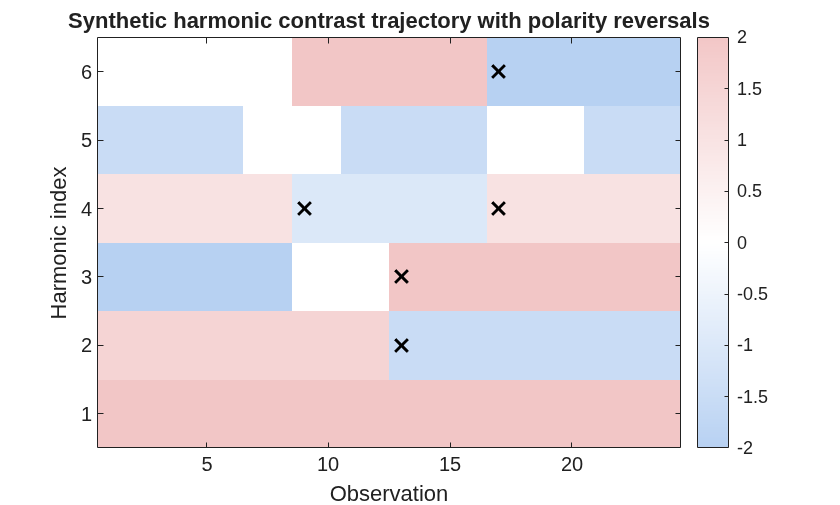

figure;

ax = axes;

% Softer diverging colormap (light blue -> white -> light red)
n = 256;
m = n/2;
blue = [0.72 0.82 0.95];
white = [1.00 1.00 1.00];
red   = [0.95 0.78 0.78];

cmapNeg = [ ...
    linspace(blue(1),  white(1), m).' ...
    linspace(blue(2),  white(2), m).' ...
    linspace(blue(3),  white(3), m).' ];

cmapPos = [ ...
    linspace(white(1), red(1), m).' ...
    linspace(white(2), red(2), m).' ...
    linspace(white(3), red(3), m).' ];

softMap = [cmapNeg; cmapPos];

% Contrast field
imagesc(ax, C.');
set(ax, YDir="normal");
colormap(ax, softMap);
clim(ax, [-max(abs(C(:))), max(abs(C(:)))]);
colorbar(ax);

xlabel(ax, 'Observation');
ylabel(ax, 'Harmonic index');
title(ax, 'Synthetic harmonic contrast trajectory with polarity reversals');

yticks(ax, 1:nHarmonics);

hold(ax, 'on');

% Overlay reversal events as x markers
[rowIdx, colIdx] = find(eventMask);

plot(ax, rowIdx, colIdx, ...
    'kx', ...
    'MarkerSize', 9, ...
    'LineWidth', 1.5);

hold(ax, 'off');

## API documentation

### MATLAB help

The MATLAB `help` command displays the class documentation extracted from its source file.

help PolarityReversalDetector

 PolarityReversalDetector Detect harmonic contrast polarity reversals.
 
  Detects changes between successive nonzero contrast polarities,
  ignoring zero-valued observations without resetting polarity state.
 
  Provides snapshot-wise detection, trajectory-wide event masks,
  and per-harmonic reversal counts and rates.

    Documentation for PolarityReversalDetector



### MATLAB documentation

The MATLAB `doc` command opens the corresponding documentation in the MATLAB Help Browser.

doc PolarityReversalDetector

## Source code

The source code of this class can be found in [`PolarityReversalDetector`](matlab:open('./PolarityReversalDetector.mlx')).

edit PolarityReversalDetector

## Test

Unit testing for the class is implemented in [`TestPolarityReversalDetector`](matlab:open('../../../tests/TestPolarityReversalDetector.m')).

res = runtests('tests/TestPolarityReversalDetector.m');

Setting up ProjectFixture
Done setting up ProjectFixture: Project 'sfrfs-toolbox' is already loaded. Setup is not required.
__________

Running TestPolarityReversalDetector
.........
Done TestPolarityReversalDetector
__________

Tearing down ProjectFixture
Done tearing down ProjectFixture: Teardown is not required.
__________



SFRFsTestUtil.printTestSummary(res, 80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestPolarityReversalDetector/initialStateHasNoEvents                             | Passed
TestPolarityReversalDetector/detectsEpisodePolarityReversals                     | Passed
TestPolarityReversalDetector/zerosDoNotResetState                                | Passed
TestPolarityReversalDetector/detectAllReturnsEpisodeEventMask                    | Passed
TestPolarityReversalDetector/summarizeReturnsCountsAndRates                      | Passed
TestPolarityReversalDetector/nonFiniteSnapshotFails                              | Passed
TestPolarityReversalDetector/emptySnapshotFails                                  | Passed
TestPolarityReversalDetector/stateSizeMismatchFails                              | Passed
TestPolarityReversalDetector/invalidStateFails                                   | Passed



The test suite contains nine tests covering state initialization, polarity reversal detection, persistence across zero-valued observations, trajectory-wide event masks, reversal counts and rates, and input validation.

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](https://doi.org/10.5281/zenodo.17631784?utm_source=chatgpt.com).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. *Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis.* In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1–9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025). DOI: 10.4230/OASIcs.DX.2025.9.

- [2] Stan Muñoz Gutiérrez and Franz Wotawa. *A Formal Framework for Spectral Fault Receptive Fields (with Examples for Bearing Health Monitoring).* Technical Report TR-SFRFs-v1.0.1, Institute of Software Engineering and Artificial Intelligence, Graz University of Technology, Graz, Austria (2026).

- [3] Stan Muñoz Gutiérrez and Franz Wotawa. *Spectral Contrast Polarity Analysis and Adaptive Sensor Fusion for Bearing Degradation Monitoring.* In Proceedings of the 2026 IEEE International Conference on Dependable Systems and Applications (DSA 2026). IEEE. (To appear; bibliographic details provisional.)